Vcc = 5;
C = 10 .* 10^-9;
V_be = 0:10^-3:5;
% V_T = 26 .* 10^-3;
k_const = 1.38064852 .* 10^-23;
q_charge = 1.60217662 .* 10^-19;
temperatures = 273 + [18 23 28];
V_T_base = k_const .* (273 + 23) ./ q_charge;
I_ref = Vcc .* 10 ^ -6

I_ref = 5.0000e-06

delta_Vb = 1 ;
% s = V_T_base .* log(2) ./ delta_Vb
s = 0.02

s = 0.0200

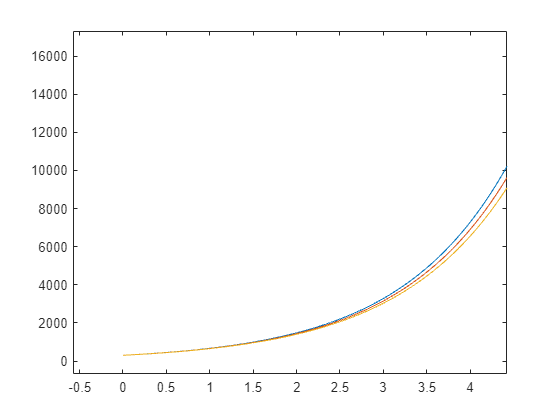

for k = 1:size(temperatures, 2)
    temperature = temperatures(k);
    V_T = k_const .* temperature ./ q_charge;
    I_cap = VI_exponential_converter(I_ref, V_T, V_be, s);
    frequency = 1./period(I_cap, C, Vcc);
    plot(V_be, frequency);
    hold on;
end

function [V_c] = V_c_function(i, C, t, Vcc) 
V_c = -i./C .* t + 2./3 .* Vcc;
end

function [T] = period(i, C, Vcc)
T = C./i .* Vcc ./ 3;
end

function [I_c] = Collector_current(V_be, V_T, I_s)
I_c = I_s .* exp(V_be./V_T);
end

function [I_cap] = VI_exponential_converter(I_ref, V_T, V_be, s)
I_cap = I_ref .* exp(s .* V_be ./ V_T);
end